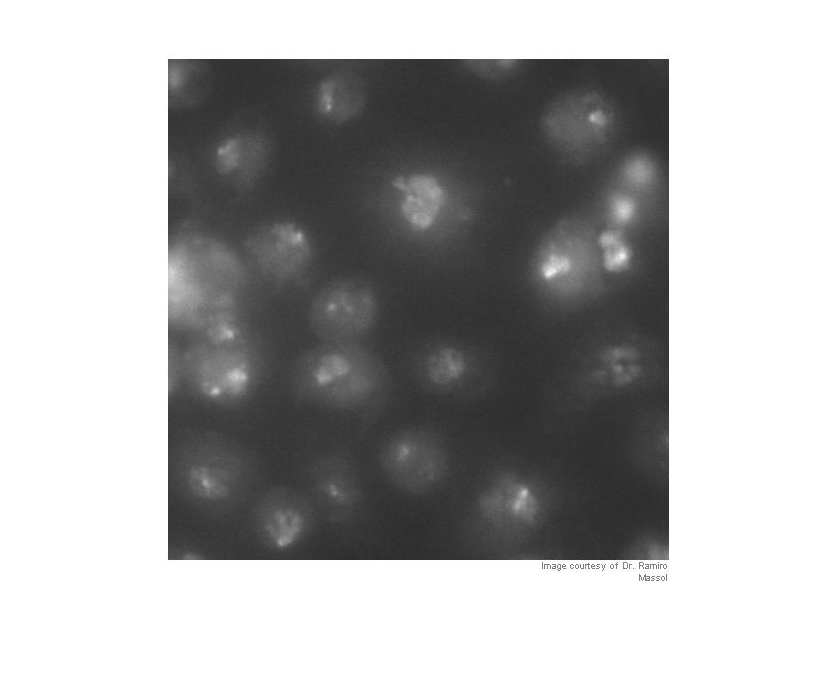

clear variables;
rgb = imread('cell_segmentation_01.jpg');

H1 = fspecial('average', 25);
H2 = fspecial('disk', 5);
H3 = fspecial('motion', 20, 45);

imshow(rgb);

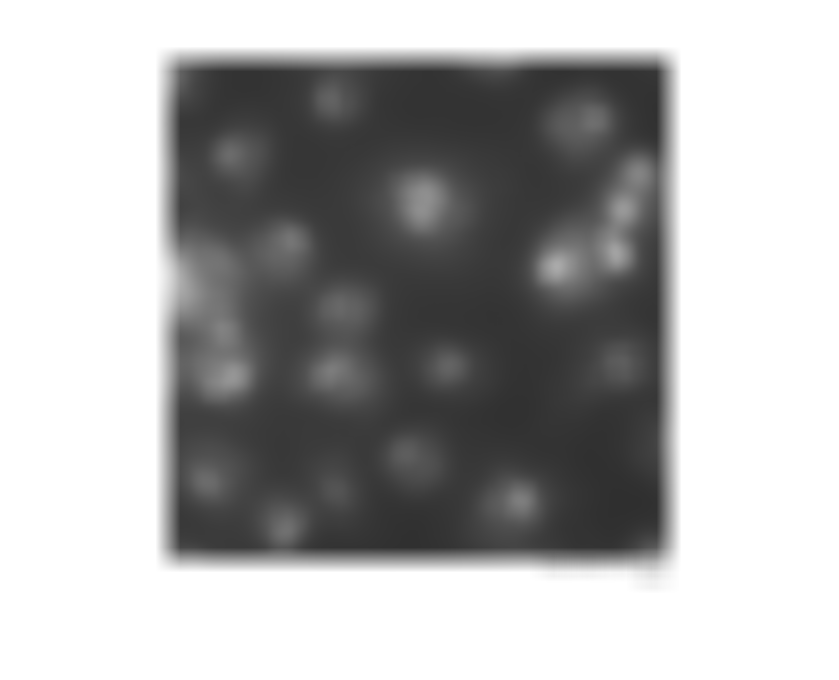

imshow(imfilter(rgb, H1, 'replicate'));

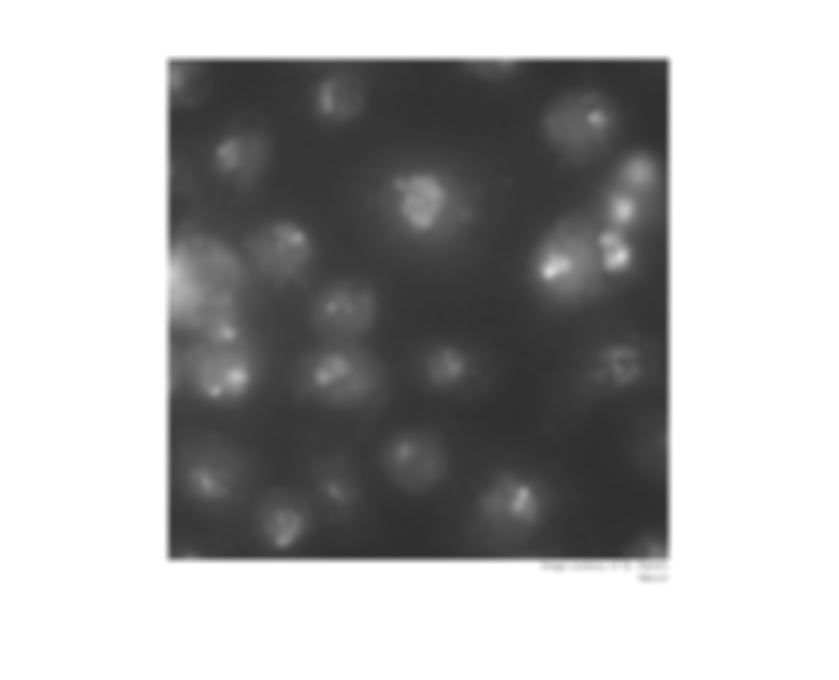

imshow(imfilter(rgb, H2, 'replicate'));

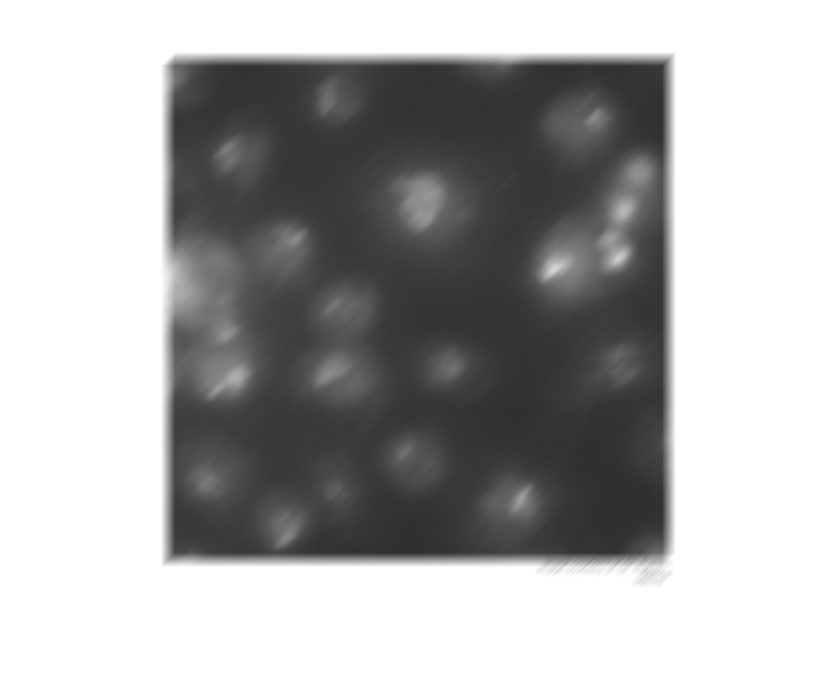

imshow(imfilter(rgb, H3, 'replicate'));

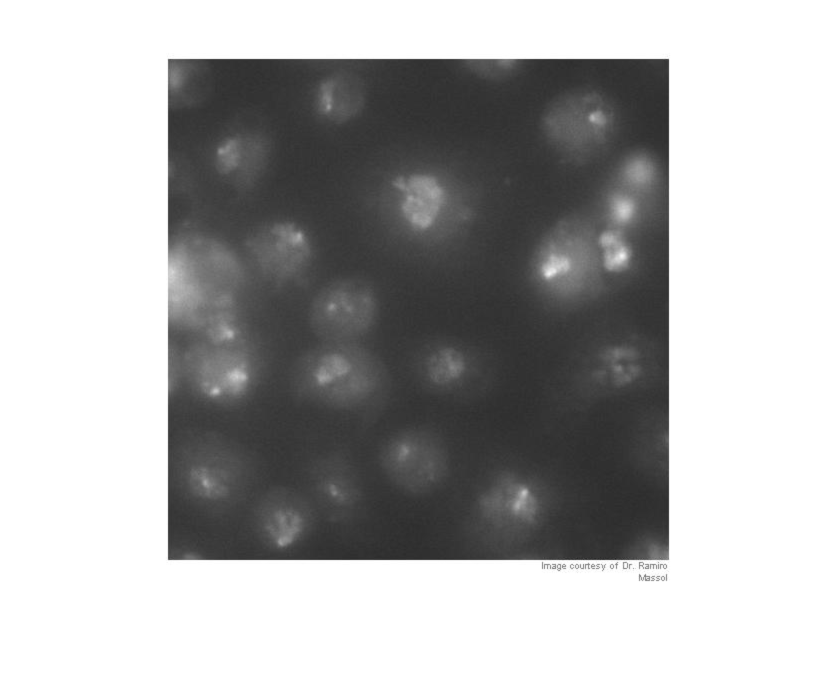

imshow(imgaussfilt(rgb));

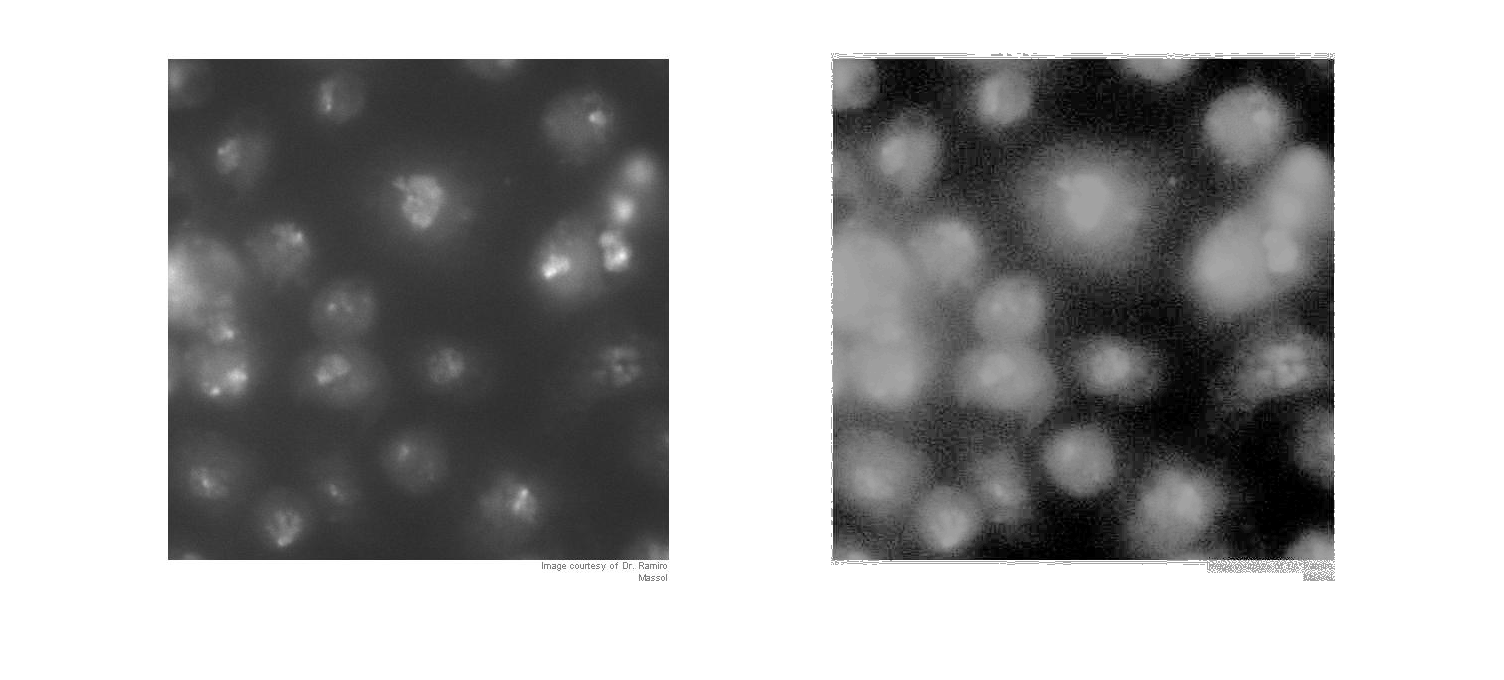


J = histeq(rgb);
imshowpair(rgb, J, 'montage');
axis off;